# n-t koordinatsystem

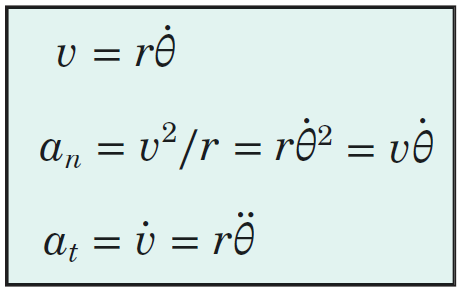


$$a_{tot} = \frac{v^2}{\rho} \cdot \overline e_n + \dot v \cdot \overline e_t$$


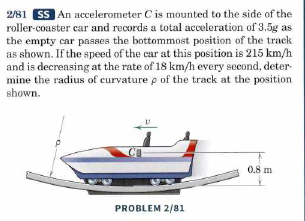

clear

g = 9.81;
v0 = 215/3.6;

at = 18/3.6;
a = 3.5 * g;

an = sqrt(a^2 - at^2)

an =        33.969



p = v0^2/an

p =           105


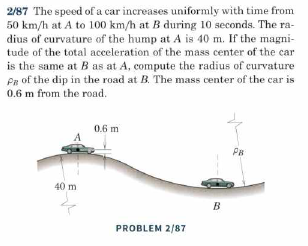

clear

va = 50/3.6;
vb = 100/3.6;
t = 10;


pa = 40 + 0.6;

at_A = va/t;
an_A = va^2/pa;

a_A = sqrt(at_A^2 + an_A^2);

% a_A = a_B

syms pb

an_B = vb^2/(pb - 0.6);

a_B = sqrt(at_A^2 + an_B^2) == a_A;

sol = solve(a_B, pb);

pb = vpa(sol, 3)

$$pb = \left(\begin{array}{c} -162.0\\ 163.0 \end{array}\right)$$

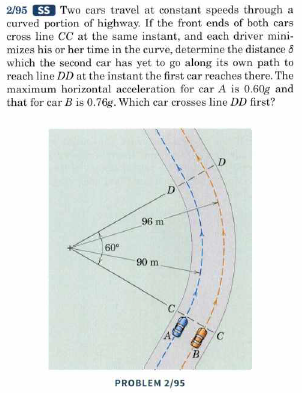

clear

g = 9.81;

% Bil A
pa = 90;
aA = 0.6*g;
theta = deg2rad(60);

% hastighed
syms va
anA = va^2/pa == aA;
va = solve(anA, va);

va = vpa(max(va),3)

$$va = 23.0$$


% tid
ta = pa*theta/va;
ta = vpa(ta,3)

$$ta = 4.09$$




% Bil Bb
pb = 96;
aB = 0.76*g;
theta = deg2rad(60);

% hastighed
syms vb
anB = vb^2/pb == aB;
vb = solve(anB, vb);

vb = vpa(max(vb),3)

$$vb = 26.8$$


% tid
tb = pb*theta/vb;
tb = vpa(tb,3)

$$tb = 3.76$$



% Bil B kommer først, bil a er bagud med

delta = vpa(va*(ta - tb),3)

$$delta = 7.76$$